
% open train image folder
traindir="/home/dmplus/2019_juniorI/CV/assignment/assignment1/dataset/AR/AR_Train_image";

if ~isfolder(traindir)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', traindir);
  uiwait(warndlg(errorMessage));
  return;
end

trainpattern=fullfile(traindir,'*.bmp');
trainimg=dir(trainpattern);
numoftrain=length(trainimg);

% read images + 2d -> 1d +  img vector concatenate to image matrix
imgmtx=[];

for i=1:numoftrain
    curfname=fullfile(traindir,trainimg(i).name);
    img=imread(curfname);
    grayscaleimg=rgb2gray(img);
    grayscaleimg=im2double(grayscaleimg);
    imgvec=grayscaleimg(:);
    imgmtx=[imgmtx,imgvec];
end

% find mean face
meanface=mean(imgmtx,2);

% value minus mean face
imgmtx=imgmtx-meanface;

% calculate covariance matrix
covmtx=cov(imgmtx');

gpuDevice

ans =   CUDADevice with properties:

                      Name: 'GeForce GTX 1060 6GB'
                     Index: 1
         ComputeCapability: '6.1'
            SupportsDouble: 1
             DriverVersion: 10.1000
            ToolkitVersion: 10.1000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 6.3703e+09
           AvailableMemory: 2.0703e+09
       MultiprocessorCount: 10
              ClockRateKHz: 1784500
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
            DeviceSelected: 1


% find eigenvalues and eigenvector
% gpucovmtx=gpuArray(covmtx);
[eigvec,eigvals,eigvec2]=svds(covmtx,9,"largest");


% reshape the vector back to image size
vectors=num2cell(eigvec,1);

matrices={};

for i=1:9
    matrices{end+1}=reshape(vectors{i},165,120);
end

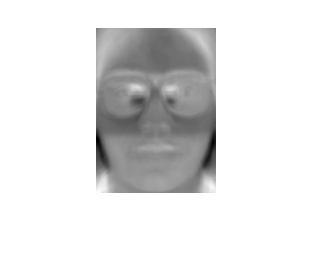

% convert matrix back to grayscale image
pathname='eigfaces/';

for i=1:9
    eigface=mat2gray(matrices{i});
    imshow(eigface);
    if(i==1 || i==5 || i==9)
        fname=strcat('d',num2str(i));
       imwrite(eigface,fullfile('eigfaces/',strcat(fname,'.bmp'))); 
    end
end

% save the eigenface and mean face to csv file
eigfacemtx=[];

for i=1:9
    grayvec=mat2gray(matrices{i});
    grayvec=grayvec(:);
    eigfacemtx=[eigfacemtx,grayvec];
end

Undefined variable matrices.


csvwrite('eigenface.csv',eigvec);


csvwrite('original_mean.csv',meanface);